`#### 1. Design criteria examples:`

`Signal factors: amplitude.`

`Economic factors: financing option.`

`Social factors: usage fear.`

`Environmental factors: weight.`

`Medical safety factors: noise or vibration.`

`#### 2. Specificity as environmental factor:`

`Specificity is the property of discerning the target signal from other signals in the envrionment. This is determined not only by the signal requirement, but also on other signals in the environment. That's why it's more appropriate to classify it in environmental factors.`

`#### 3. Oscilloscope`

`a. Input has 4 divisions from peak-to-peak, resulting in $``4``\times``0.5``=``2``$`` volts.`

`Output has 2 divisions from peak-to-peak, resulting in $``2``\times``0.1``=``0.2``$`` volts.`

`b. Gain for this system is $``V_{out}/V_{in}=``0.2``/``2``=``0.1``$`

`c. Frequency: the signal has period of about 6.6 divisions with time base of 0.2ms/div, resulting in $``T=``0.2``\times``6.6``=``1.32``$`` ms. Frequency = $``(``1``/``1.32``)\times``1000``=``757``$`` Hz.`

`d. The output signal lag is about 1.6 divisions, with period of about 6.6 divisions. Lag in degrees: $``1.6``/``6.6``\times``360``=``87.3``\degree``$`

`e. The input signal is 1.8 division above arrow 1, so the offset is $``1.8``\times``0.5``=``0.9``$`` volts.  `

`The output signal is 0.6 division above arrow 2, so the offset is $``0.6``\times``0.1``=``0.006``$`` volts.`

#### `4. Mean and RMS`

syms t w
B = 1;
A = 2;

% Signal
s = B + A*sin(w*t);

% Part (a): T = 2*pi/w (one period of the signal)
T_a = 2*pi/w;

% Mean value
mean_a = (1/T_a) * int(s, t, 0, T_a);

% RMS value
rms_a = sqrt((1/T_a) * int(s^2, t, 0, T_a));

disp('4a:');

4a:


disp(['Mean: ', char(mean_a)]);

Mean: 1


disp(['RMS: ', char(rms_a)]);

RMS: 3^(1/2)



% Part (b): T = 3*pi/w (one and a half period of the signal)
T_b = 3*pi/w;

% Mean value
mean_b = (1/T_b) * int(s, t, 0, T_b);

% RMS value
rms_b = sqrt((1/T_b) * int(s^2, t, 0, T_b));

disp('4b:');

4b:


disp(['Mean: ', char(mean_b)]);

Mean: (3*pi + 4)/(3*pi)


disp(['RMS: ', char(rms_b)]);

RMS: (3*pi + 8/3)^(1/2)/pi^(1/2)


#### 5

disp('5:');

5:



% Transfer function
syms K tau1 w
H = (K * tau1 * 1i*w) / (tau1 * 1i*w + 1);

% Magnitude
magnitude = abs(H);

% Phase
phase = angle(H);

disp(['Magnitude: ', char(magnitude)]);

Magnitude: abs(K*tau1*w)/abs(tau1*w*1i + 1)


disp(['Phase (radians): ', char(phase)]);

Phase (radians): angle((K*tau1*w*1i)/(tau1*w*1i + 1))


#### 6

disp('6:');

6:


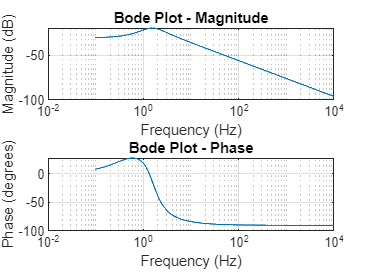

% Transfer function
num = [1 3]; % Numerator coefficients (s + 3)
den = [1 10 100]; % Denominator coefficients (s^2 + 10s + 100)

% Frequency range
f = logspace(-1, 4, 500); % 0.1 Hz to 10,000 Hz
w = 2*pi*f;

% Evaluate transfer function
H = freqs(num, den, w);

% Magnitude and phase
magnitude = abs(H);
phase = angle(H) * (180/pi); % Convert to degrees

% Plot Bode plot
figure;
subplot(2, 1, 1);
semilogx(f, 20*log10(magnitude)); % Magnitude in dB
grid on;
title('Bode Plot - Magnitude');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(2, 1, 2);
semilogx(f, phase); % Phase in degrees
grid on;
title('Bode Plot - Phase');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');

c. 3

d. 2

e. 2

f. 3

g. 2

h. 3

i. 2

j. 1

k. 2

l - m. 1

n. 3

o. 2

p. 1

q. 2

r. 4

s. 3

t. 1

u. 3